Let's see if translation in mouse brain camera view can be automatically fixed. Let's first get the data.

reader = mouse.read.TiffVideoReader;
data = reader.read('M:\190626-G19M1-fc1.tif');
data = reshape(data,128,128,4,[]);
data = data(:,:,:,101:end);
chData = squeeze(data(:,:,1,:));

This data has several movements.

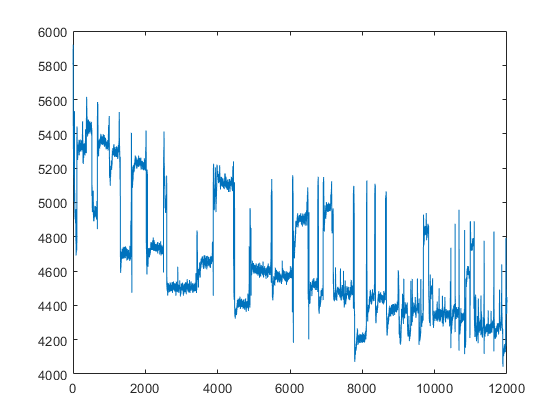

figure; plot(squeeze(chData(79,79,:)));

Let's try correcting it by calculating the translation matrix between each frame to the next.

newChData = zeros(size(chData));
newChData(:,:,1) = chData(:,:,1);

[optimizer, metric] = imregconfig('monomodal')

optimizer =   registration.optimizer.RegularStepGradientDescent

  Properties:
    GradientMagnitudeTolerance: 1.000000e-04
             MinimumStepLength: 1.000000e-05
             MaximumStepLength: 6.250000e-02
             MaximumIterations: 100
              RelaxationFactor: 5.000000e-01

metric =   registration.metric.MeanSquares

  This class has no properties.


for frameInd = 2:100
    moving = chData(:,:,frameInd);
    fixed = newChData(:,:,frameInd-1);
    tform = imregtform(moving,fixed,'translation',optimizer,metric);
    movingRegistered = imwarp(moving,tform,'OutputView',imref2d(size(fixed)));
    newChData(:,:,frameInd) = movingRegistered;
end


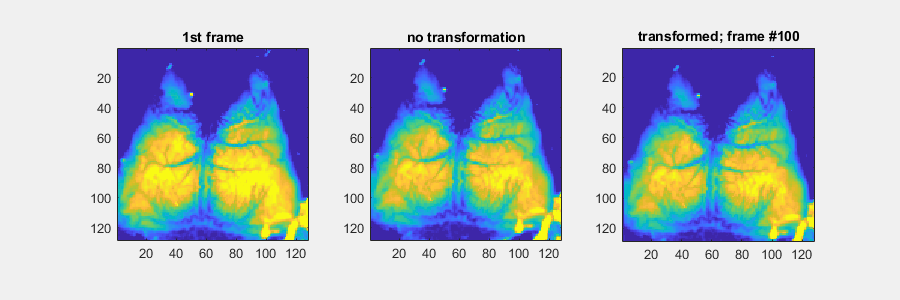

figure('Position',[100 100 900 300]); set(gcf,'Visible','on')
for frameInd = 1:100
    subplot(1,3,1);
    imagesc(chData(:,:,1),[3000 6000]); axis(gca,'square');
    title('1st frame');
    subplot(1,3,2);
    imagesc(chData(:,:,frameInd),[3000 6000]); axis(gca,'square');
    title('no transformation');
    subplot(1,3,3);
    imagesc(newChData(:,:,frameInd),[3000 6000]); axis(gca,'square');
    title(['transformed; frame #' num2str(frameInd)]);
    drawnow;
    pause(0.15);
end